names = 1×2 string array
    "image1"    "image2"


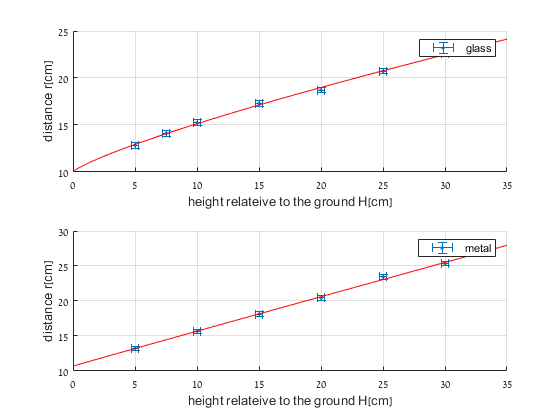

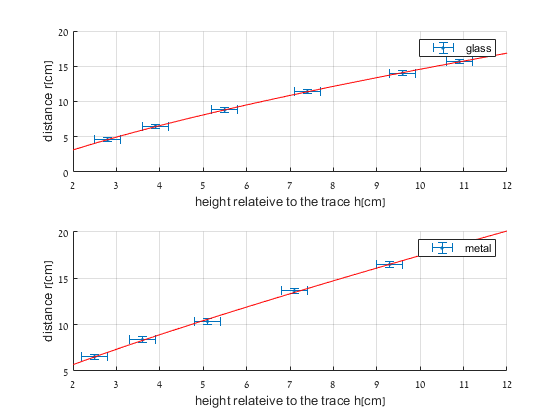

names = 1×2 string array
    "var1"    "var2"


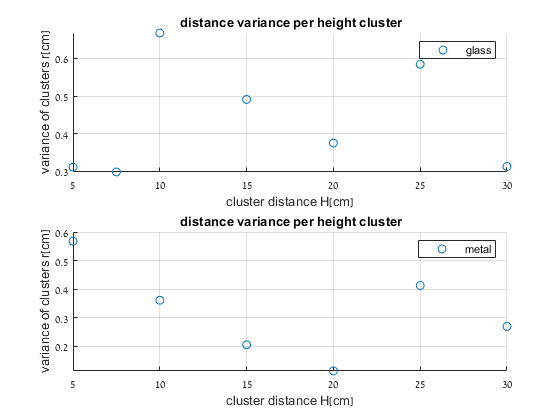

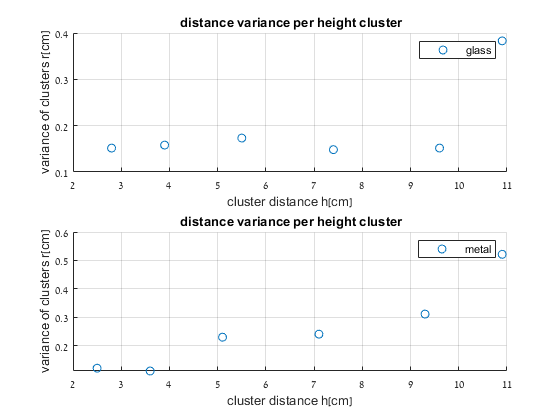

names = 1×2 string array
    "logimage1"    "logimage2"


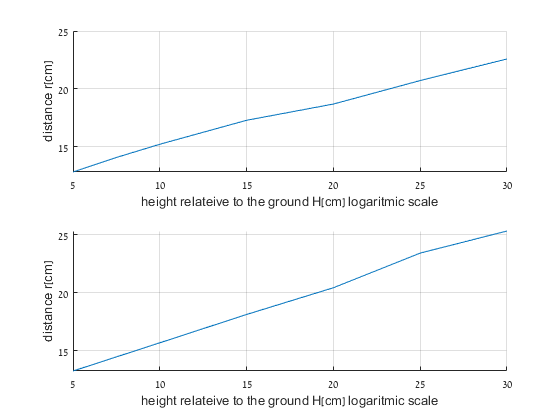

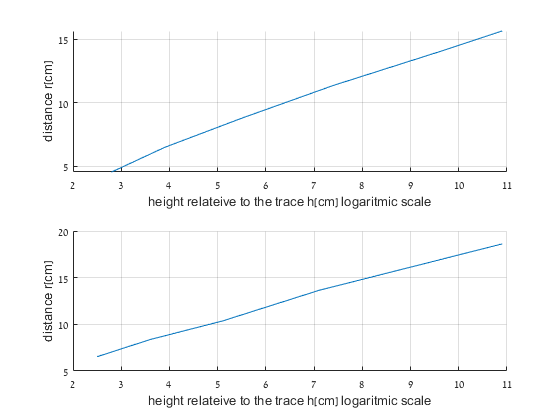

names = 1×2 string array
    "loglogvar1"    "loglogvar2"


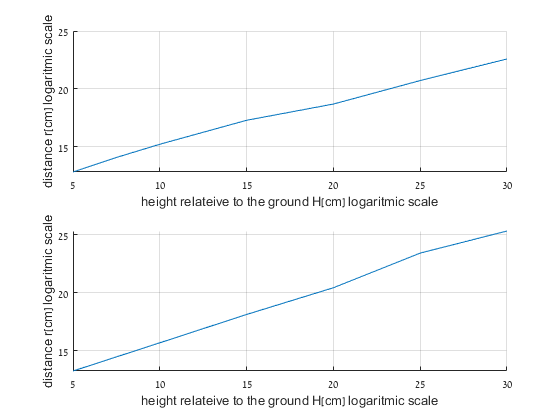

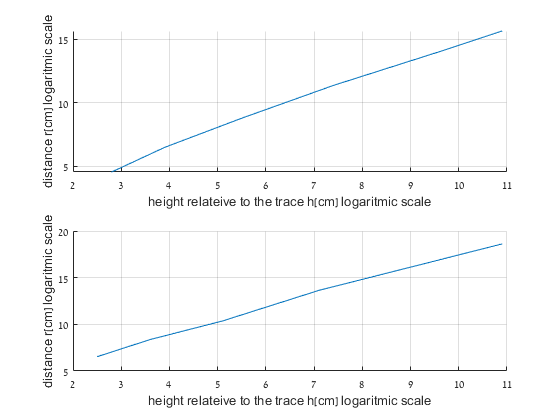

A = SessionH(G1 , "glass");
B = SessionH(G2 , "metal");
C = Sessionsmallh(G3 , "glass");
D = Sessionsmallh(G4 , "metal");
Glist = {A B C D };
loopplot(Glist , "");

Glist = {objkinect(A) objkinect(B) objkinect(C) objkinect(D)}

Glist = 1×4 cell array
    {1×1 Session}    {1×1 Session}    {1×1 Session}    {1×1 Session}


names = 1×2 string array
    "image1_Ek"    "image2_Ek"


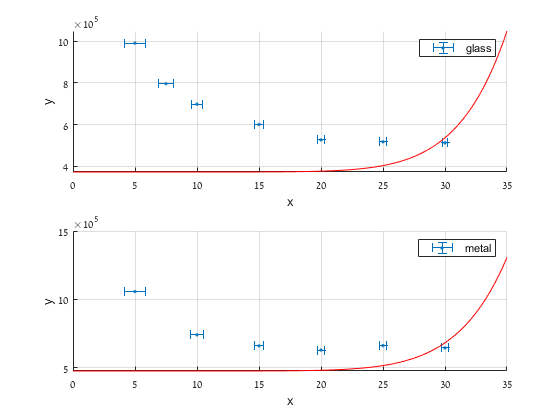

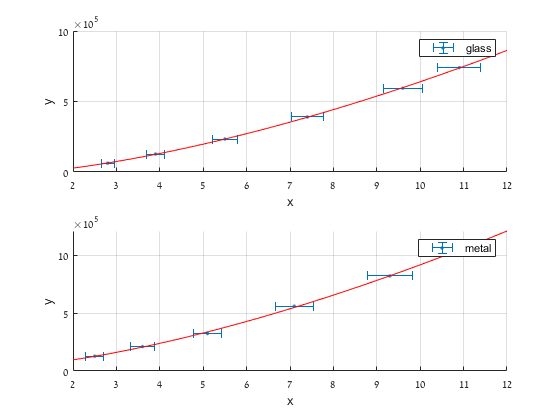

names = 1×2 string array
    "var1_Ek"    "var2_Ek"


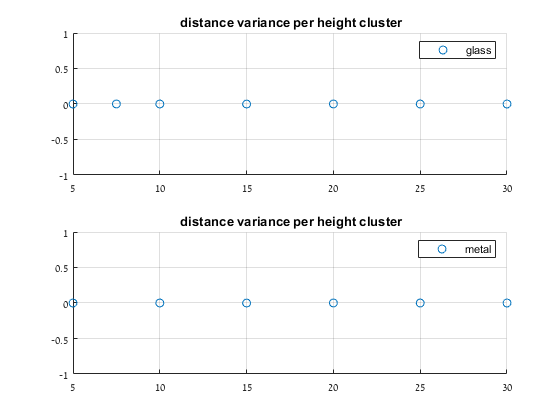

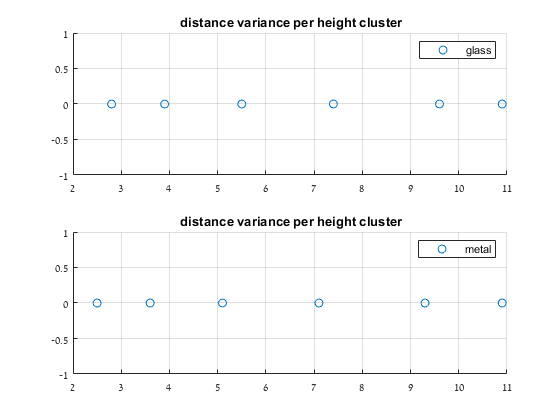

names = 1×2 string array
    "logimage1_Ek"    "logimage2_Ek"


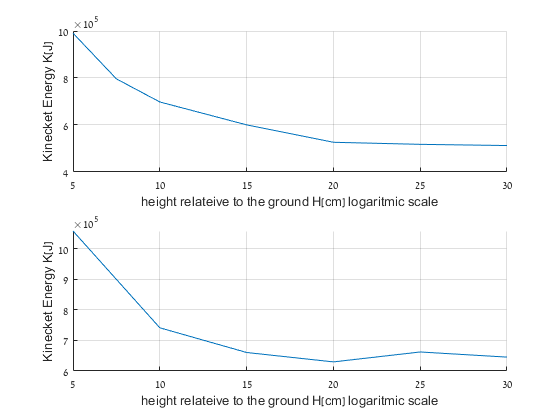

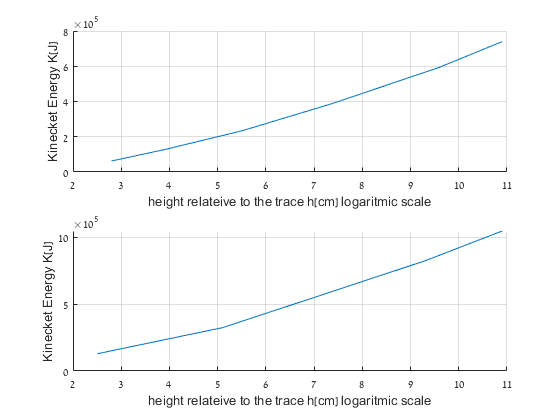

names = 1×2 string array
    "loglogvar1_Ek"    "loglogvar2_Ek"


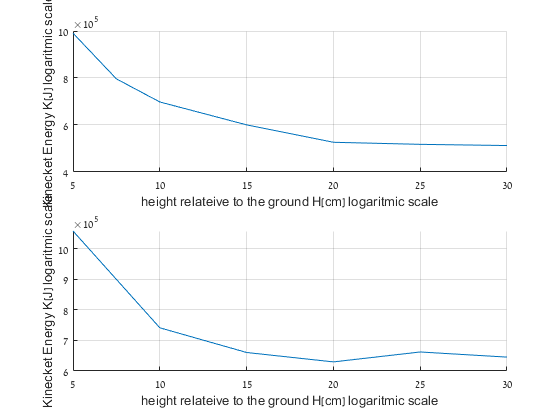

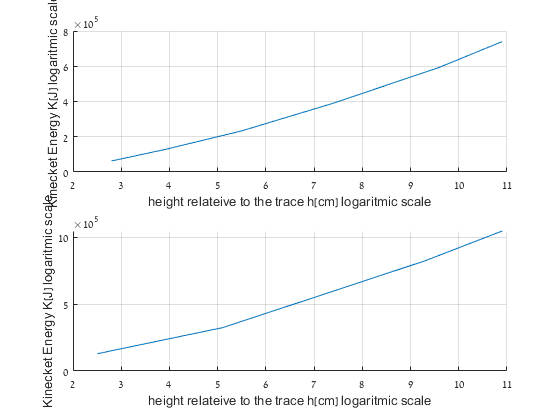

loopplot(Glist , "_Ek")

function loopplot(Glist , namehist)
    names = [ strcat("image1" ,  namehist) , strcat("image2",  namehist)]
    pr(@plot , Glist ,names );
    names = [strcat("var1"  ,namehist ) , strcat("var2" , namehist)]
    pr(@var , Glist ,names );
    names = [ strcat("logimage1",namehist)  , strcat("logimage2" ,namehist)]
    pr(@plotlog, Glist ,names );
    names = [strcat("loglogvar1",namehist) , strcat("loglogvar2"  ,namehist)]
    pr(@loglog , Glist ,names );
end

function pr(foo , Glist , names)
    figure();
    for i = 1:2
        for j = 1:2
            sp = subplot(2,1,j);
            grid on 
            hold(sp , 'on');
            index = 2*(i-1)+j;
            foo(Glist{index});
            hold(sp , 'off');
            if mod(j,2) == 0
                print(strcat("./png/" , names{i}), "-dpng")
                figure();
            end
        end
    end
end

